# LSTM Layer as a Nonlinear Dynamical System

This example explains how an LSTM (Long Short-Term Memory) layer can be seen as a nonlinear dynamical system having a specific structure, and sheds some light on whether, and how, an LSTM layer can approximate a linear dynamical system.

## Introduction to LSTM Networks and References

LSTM are a particular class of *gated* recurrent neural networks (RNNs).

The central idea of RNNs is to add both *memory* (that is, *states*) and *feedback* to a neural network to allow *current output* values to depend on *past* *output* values. From an electrical engineering perspective there is a direct analogy between RNNs and IIR (infinite impulse response) filters, in which the current output is the weighted sum of past inputs *and outputs* (as opposed to finite impulse response -FIR- filters in which the current output is the weighted sum of only past inputs). Indeed, just as in IIR filters, the current output of an RNN can depend on inputs and outputs of an arbitrarily distant past, or in other words, it is possible that inputs or outputs are never completely forgotten (this happens when the linear approximation of its internal feedback loops have gains with eigenvalues close to one).

The idea behind *gated* RNNs (of which LSTMs are a subset) is to add multiplicative *gates* that are controlled by other neurons. These gates allow, among other things, to reset the RNN states to zero (therefore allowing the memory to be forgotten). This results in an increased versatility of the network for problems in which the input sequence is context-dependent.

For a good introduction on RNNs, see [Chapter 10, Deep Learning](https://www.deeplearningbook.org/contents/rnn.html), I. Goodfellow, J. Bengio and A. Courville). For a shorter introduction, see [Understanding LSTMs](https://colah.github.io/posts/2015-08-Understanding-LSTMs/) (C. Olah). See [LSTM](https://en.wikipedia.org/wiki/Long_short-term_memory) (wikipedia) for a short summary.

For a more hands-on and MATLAB®-based starting point, see [LSTM Networks](https://www.mathworks.com/help/deeplearning/ug/long-short-term-memory-networks.html) and, for a concise description of the layer itself, see [LSTM Layer](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.lstmlayer.html).

## LSTM Layer: Simulink® Model

This section shows a Simulink implementation of an LSTM layer followed by a simple fully connected (FC) layer. This is done mostly to show the structure of an LSTM in a visual, yet detailed, way. If you don't have Simulink you can just read on, look at the picture, comment the call to the `sim` command, and move on.

The Simulink implementation of an LSTM layer followed by an FC layer is shown in the following picture.

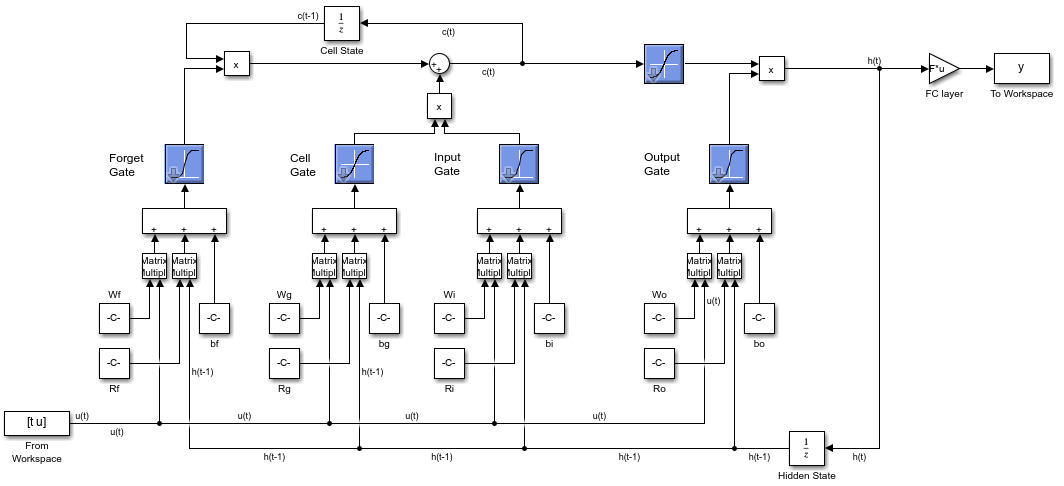

The input to the network is a vector of `Ni` components, each of which is an (independent) function of time, that is, a sequence of values. In what follows, the input sequence is indicated with $u\left(t\right)$, in line with normal notation used in the control community (the notation $x\left(t\right)$ is instead more commonly used to indicate network inputs in the machine learning community).

The LSTM layer uses `Nn` neurons (units). Each LSTM unit is associated wit two states, a cell state and a hidden state. The updates to both states are regulated by four *gates* (named input, forget, cell candidate and output gates, respectively) which are `sigmoid` or `tansig` activated functions of all inputs and states. Specifically, the cell candidate gate is activated by a `tansig` (hyperbolic tangent) function, the other gates are activated by a sigmoid function.  

The $h\left(t\right)$ vector, which contains the hidden states of all the units as components, is also the output of the LSTM layer. The LSTM layer is followed by a fully connected linear layer (for this example being just the matrix gain $F$), which takes the vector of `Nn` hidden states $h\left(t\right)$ as input and outputs a vector of `No` components.

Note that the three sigmoid-shaped and the two tansig-shaped activation functions not only allow nonlinear function approximations, especially when multiple LSTM layers are placed in series, but also prevent the magnitude of the signals flowing in the loop to reach one. This allows information to persist while at the same time preventing loop signals from growing indefinitely and backpropagation gradients to vanish.

## Set Parameters and Simulate the Model

To simulate the model, first, define the number of neurons, as well as the number of inputs and outputs of the network. Define a network with three inputs, four neurons in the LSTM layer, and two outputs (to change the dimension of any of these signals, modify the following line).

Nn = 3; Ni = 4; No = 2;

To ensure reproducibility, fix the seed of the random generator.

rng(0)

Define random initial states.

h0 = rand(Nn,1);
c0 = rand(Nn,1);

The weight matrix $W$ connects each network input to each of the four gates of each unit. Specifically, $W=\left\lbrack W_i \;;W_f \;;\;W_g \;;\;W_o \right\rbrack$, where the subscripts, $i$,$f$,$\;g$, and $o$ denote the input, forget, cell candidate and output gates, respectively (and the semicolon indicates vertical stacking). Define $W$ as a random array.

W = rand(4*Nn,Ni); 

The weight matrix $R$ connects the hidden state of each unit at the previous time step, $h\left(t-1\right)$, to each of the four gates of each unit. Specifically, $R=\left\lbrack R_i \;;R_f \;;\;R_g \;;\;R_o \right\rbrack$.  Define $R$ as a random array.

R = rand(4*Nn,Nn);

The bias vector $b$ contains the biases for each of the four gates, for each unit. Specifically, $b=\left\lbrack b_i \;;b_f \;;\;b_g \;;\;b_o \right\rbrack$. Define $b$ as a random array.

b = rand(4*Nn,1);

Finally define the fully connected layer matrix $F$, which produces the network outputs from $h\left(t\right)$, as a random array with no bias.

F = rand(No,Nn);

Define a time vector, `t`, with a sampling time `0.1` seconds, and random input sequence, `u`.

Ts = 0.1;
t = (0:Ts:50*Ts)';
u = randn(length(t),Ni);

The **From Workspace** block supplies the input sequence to the model, and the **To Workspace** block returns the output sequence in the workspace variable `y`. 

Simulate the model and display the first 5 samples of the output.

sim("lstm_sim");
y(1:5,:)'

ans =     0.5624    0.4918    0.5669    0.1661    0.0300
    1.3426    1.1631    1.3554    0.3430    0.0593


## LSTM Layer: Deep Learning Toolbox™

In this section, use the Deep Learning Toolbox to define and simulate the exact same network that you have previously defined and simulated with Simulink.

First, define the network as an array of layer objects. Use a regression layer as a final output layer (this instructs the training algorithm to compute the half-mean-squared-error loss for regression).

layers = [
   sequenceInputLayer(Ni)
   lstmLayer(Nn)
   fullyConnectedLayer(No)
   regressionLayer
];

Set the LSTM layer weights.

layers(2).InputWeights = W;
layers(2).RecurrentWeights = R;
layers(2).Bias = b;

Set the  LSTM layer states.

layers(2).HiddenState = h0;
layers(2).CellState = c0;

Set the weights of the fully connected layer (without loss of generality, keep the bias to zero).

layers(3).Weights = F;
layers(3).Bias = zeros(No,1);

Assemble layers into a series network object (this is necessary for training or predicition).

snet = assembleNetwork(layers);  

Calculate the network output when given `u` as input (the second input argument of `predict` must have time as a second dimension, so it is `u'` instead of `u`).

z = predict(snet,u');

Display the first five samples of `z`.

z(:,1:5)

ans = 2×5 single matrix
    0.5624    0.4918    0.5669    0.1661    0.0300
    1.3426    1.1631    1.3554    0.3430    0.0593


Display the norm of the difference between `z` and `y`.

norm(z'-y)

ans = single
5.8006e-07

The numerical difference is caused by the fact that while the Simulink model operates using the `double` format, the network operates using the `single` format. Apart from that, the result confirms that the two different representations of the LSTM are identical. 

## Connecting Multiple LSTM Layers in Series

You can also connect another LSTM layer, indeed any number of LSTM layers, instead of the gain matrix $F$. It is well known that, loosely speaking, multiple nonlinear layers help to approximate efficiently (that is with exponentially less neurons) many "compositional" functions. For more information see [Chapter 6, Deep Learning](https://www.deeplearningbook.org/contents/mlp.html).

Note however that the number of parameters of an LSTM layer scales quadratically with the number of units (see the $R$ matrix) and is in part multiplied by the number of inputs (see the $R$ matrix), leading to a considerable growth in the number of total weights when connecting multiple LSTM layers in series. For example, suppose you are connecting two LSTM layers in series, and that both layers have 100 units. This implies that the $R$ matrices of both layers have 40000 elements. Additionally, since the number of inputs of the second layer must also be 100, the second layer has a $W$ matrix of 40000 elements, leading already to a total of 120000 elements even without considering the biases or the $W$ matrix of the first layer.

# How Well Can LSTMs Approximate Linear Systems?

Attempting to answer this question sheds some light on the general approximation capabilities of LSTMs, and on the class of systems for which using an LSTM for system identification can potentially make some sense. Comparing the solution provided by a training algorithm to a solution that is manually calculated from the true system matrices also provides interesting insights.

## Define and Simulate Linear System

First, define a sample time and a linear discrete-time system. 

Create the system in zero-pole-gain form, convert to discrete time, and then convert to state space form.

Ts = 0.01;
sys = ss(c2d(zpk(-4,[-9+5i;-9-5i;-2+50i;-2-50i],5e5),Ts));

This system is the one used in the example [Use LSTM Network for Linear System Identification](https://www.mathworks.com/help/ident/ug/use-lstm-for-linear-system-identification.html). It is a fourth-order system, with a relative degree equal to three (in continuous time), which exhibits mixed fast and slow dynamics with moderate damping. These characteristics pose a challenge to any nonlinear structure that you use for system identification, as such structure must be able to capture both the fast and the slow dynamics before the responses fades out.

In what follows $A$, $B$, $C$, and $D$ are the state space matrices and $x\left(t\right)$ is the state of the discrete-time system. For more information on how to handle linear time-invariant systems in MATLAB, see [Linear (LTI) Models](https://www.mathworks.com/help/control/getstart/linear-lti-models.html).

Display the system static gain (the $D$ matrix) its steady state gain (which is, for discrete time systems, ${C\left(I-A\right)}^{-1} B+D$).

sys.D

ans = 0

dcgain(sys)

ans = 7.5351

Display the system in zero-pole-gain form.

zpk(sys)

ans =
 
     0.078673 (z+3.517) (z-0.9608) (z+0.2599)
  ----------------------------------------------
  (z^2 - 1.826z + 0.8353) (z^2 - 1.72z + 0.9608)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.
Model Properties


Note that all zeros are on the real axis.

Define the number of units (neurons), inputs and outputs for the network. Use as many neurons as the system states, and (obviously) the same number of input and output of the system to be approximated.

Nn = size(sys.B,1); Ni = size(sys.B,2); No = size(sys.C,1);

Define a time vector and random input sequence.

t = 0:Ts:50*Ts;
u = randn(length(t),Ni);

Without loss of generality, set the initial state for the linear system to zero.

x0 = zeros(Nn,1);

Simulate the linear system using the [`lsim`](https://www.mathworks.com/help/ident/ref/lti.lsim.html) function. Transpose the response to obtain a row vector, and store it the variable `y`.

y = lsim(sys,u,t,x0)';

## Define and Simulate LSTM with Calculated Weights

In this section, calculate a set of weights that approximate the linear system, and then simulate the network with these weights to verify the quality of the approximation.

Define the network as an array of layer objects.

layers = [
   sequenceInputLayer(Ni)
   lstmLayer(Nn)
   fullyConnectedLayer(No)
   regressionLayer
];

Define a scaling factor to scale the network operations in an neighborhood of zero, in which the hyperbolic tangent activation functions behave as linear (identity) functions. The network inputs are scaled down by this factor and the outputs are scaled up.

scl = 1e-3;

Set the LSTM weights so that:

- The output of the cell candidate gate activation function approximates $\textrm{Ah}\left(t-1\right)+\textrm{Bu}\left(t\right)$ , where $u\left(t\right)$ is the network input. This means letting $h\left(t-1\right)$ play the part of the linear system state $x\left(t\right)$, and can be achieved by setting $R_g =A$, $W_g =B$, and $b_g =0$. 

- The output of the input and output gates activation functions is very close to one, which amounts to disregarding these gates altogether. This can be achieved setting both $b_i$ and $b_o$ to a large number, and the corresponding $W$ and $R$ matrices to zero.

- The output of the forget gate activation function is zero, which implies disregarding the cell state $c\left(t\right)$. This can be achieved by setting $b_f$ to a very small number and the corresponding $W$ and $R$ matrices to zero.

W = scl*[zeros(Nn,Ni); zeros(Nn,Ni); sys.B; zeros(Nn,Ni)];
R = [zeros(Nn) zeros(Nn) eye(Nn) zeros(Nn)]'*sys.A;
b = [1e2*(ones(1,Nn)) -1e2*(ones(1,Nn)) 0*(ones(1,Nn)) 1e2*(ones(1,Nn))]';

Ideally we would set the output gain matrix $F$ so that the network output $\textrm{Fh}\left(t\right)=F\left(\textrm{Ah}\left(t-1\right)+\textrm{Bu}\left(t\right)\right)$ is equal to the LTI system output, $\textrm{Cx}\left(t\right)+\textrm{Du}\left(t\right)$.

Assuming $x\left(t\right)\approx h\left(t-1\right)$ this would result in:


$$F\left(h\left(t-1\right),u\left(t\right)\right)=\left(\textrm{Ch}\left(t-1\right)+\textrm{Du}\left(t\right)\right)\;{\left(\textrm{Ah}\left(t-1\right)+\textrm{Bu}\left(t\right)\right)}^{-1}$$


Since we can only select a constant matrix, a reasonable compromise is to prioritize the dependence on $h\left(t-1\right)$, instead of the dependence on $u\left(t\right)$, and select $F=CA^{-1}$. This choice of  results in the following network output:


$$y=CA^{-1} \textrm{Ah}\left(t-1\right)+CA^{-1} \textrm{Bu}\left(t\right)=\textrm{Ch}\left(t-1\right)+CA^{-1} \textrm{Bu}\left(t\right)$$


It's important to notice that, using this kind of approximation, we end up with a static gain $D_{\textrm{LSTM}} =CA^{-1} B$. 

Therefore, *when selecting the LSTM parameters this way*, the more the $D$ matrix in your linear system deviates from $CA^{-1} B$, the worst its LSTM approximation is bounded to be.

In other words, assuming that the scaling factor keeps the signals in a range in which the `tansig` function is indistinguishable from the identity function, this choice of LSTM weights produces a very accurate approximation of the following linear system:

mss=ss(sys.A,sys.B,sys.C,sys.C*inv(sys.A)*sys.B,Ts);

Display the (nonzero) $D$ matrix.

mss.D

ans = 0.0861

 Since $D$ is positive, the steady state gain is slightly larger than the one of the original linear system.

dcgain(mss)

ans = 7.6212

Display the system in zero-pole-gain form.

zpk(mss)

ans =
 
    0.0861 z (z-0.9606) (z^2 - 1.672z + 5.904)
  ----------------------------------------------
  (z^2 - 1.826z + 0.8353) (z^2 - 1.72z + 0.9608)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.
Model Properties


As expected, the fact that there is a nonzero $D$ leads to the system having as many zeros as poles (i.e. a zero relative degree). Note that two zeros are on the real axis (one of them being in the origin), but, differently from the original system, the other two are not on the real axis.

The linear system to be approximated in this example has a $D$ matrix equal to zero. Nevertheless set $F$ as indicated and scale the output back from the neighborhood of zero to the intended range.

F = sys.C/sys.A/scl;

Set the LSTM weight matrices.

layers(2).InputWeights = W;
layers(2).RecurrentWeights = R;
layers(2).Bias = b;

Set the LSTM states. Since the initial state of `sys` is assumed to be zero, set the LSTM state vectors to zero as well.

layers(2).HiddenState = zeros(Nn,1);
layers(2).CellState = zeros(Nn,1);

Set the weight matrix of the fully connected layer.

layers(3).Weights = F;
layers(3).Bias = zeros(No,1);

Assemble layers into a series network object.

snet = assembleNetwork(layers);

Calculate network output sequence.

z = predict(snet,u');

## Compare outputs

To compare the outputs, plot `y` and `z`.

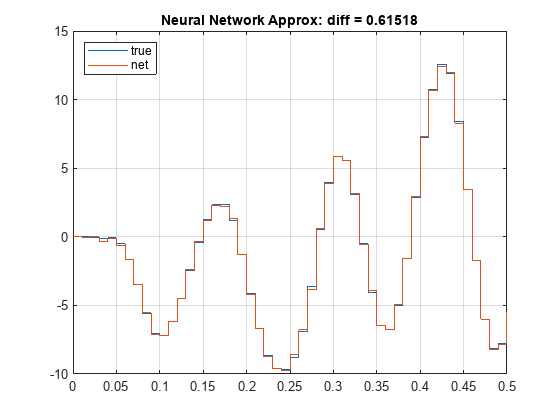

stairs(t',[y' z']);
legend("true","net",Location="northwest");
title(['Neural Network Approx: diff = ' num2str(norm(y-z)) ])
grid

Despite the unavoidable approximation errors caused by the fact that the linear system to approximate has a $D$ matrix equal to zero, by the fact that the hyperbolic tangent functions in the LSTM deviate from linearity for higher input magnitudes, and (in very minor part) by the fact that the output of the sigmoid functions are never exactly zero or one, the LSTM still provides a very good approximation of the linear system.

# Train the LSTM to Approximate the Linear Systems

In reality, in a system identification problem, you only have access to the input and output signals of an unknown system, and you don't have any system representation (much less the $A$, $B$ and $C$ matrices of the linearized system) that you can leverage to set the weights of the LSTM network. Therefore, you have to estimate a sufficient number of neurons (you might or might not have an idea about the dimension of the state space of the system that generated the signals), start with random weight matrices, and rely on the training algorithm to find the best weight matrices that hopefully enable the LSTM to reproduce the validation output signal from the validation input one.

This problem is discussed in more detail in the example [Use LSTM Network for Linear System Identification](https://www.mathworks.com/help/ident/ug/use-lstm-for-linear-system-identification.html). However, given the fixed structure used in the previous section (a single LSTM layer with as many neurons as states followed by a fully connected layer), it is of interest to find out if the training algorithm, starting from random initial weights, can find a solution which is close enough to (or possibly better than) the one calculated from the true system matrices.

A related question is what happens if the training algorithm is started directly from the calculated weights. In this case how much would the solution deviate (if at all) from the one shown in the previous section?

The following sections answer both questions.

## Define Training Input and Output Sequences

Define a training time vector and a random training input signal. For the training data, use more points than you used to compare outputs in the previous section.

ttr = 0:Ts:1e3*Ts;
utr = randn(length(ttr),Ni);

Without loss of generality, set the initial state for the linear system to zero.

x0 = zeros(Nn,1);

Simulate the linear system using the [`lsim`](https://www.mathworks.com/help/ident/ref/lti.lsim.html) function, storing the response in the workspace variable `ytr`.

ytr = lsim(sys,utr,ttr,x0)';

## Define Network Training Options

For this example, use the Adam (name derived by adaptive momentum) algorithm with an initial learning rate of 0.0001. Set the learning rate schedule so that it drops by 99% every 100 steps. Set the gradient truncation threshold to 1, and use 10000 epochs used to train the network. Use the `Verbose` option to display the training progress (once every 500 steps) at the command line. 

opts = trainingOptions("adam",...
    InitialLearnRate=0.0001,...
    LearnRateSchedule="piecewise",...
    LearnRateDropPeriod=100,...
    Plots="none",...
    Verbose=true, ...
    VerboseFrequency=500, ...
    LearnRateDropFactor=0.99,...
    GradientThreshold=1,...
    MaxEpochs=10e3);

## Train the Network

To train the network, starting from the previously calculated weights, use `trainNetwork`. Transpose the input sequence so that time is along the second dimension. 

snet = trainNetwork(utr',ytr,layers,opts);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |         0.10 |      4.8e-03 |      1.0000e-04 |
|     500 |         500 |       00:00:15 |         0.64 |          0.2 |      9.6060e-05 |
|    1000 |        1000 |       00:00:29 |         0.59 |          0.2 |      9.1352e-05 |
|    1500 |        1500 |       00:00:44 |         0.69 |          0.2 |      8.6875e-05 |
|    2000 |        2000 |       00:00:59 |         0.61 |          0.2 |      8.2617e-05 |
|    2500 |        2500 |       00:01:14 |         0.39 |      7.6e-02 |      7.8568e-05 |
|    3000 |        3000 |       00:01:29 |         0.32 |      5.2

The output `snet` is the trained network, returned as a `SeriesNetwork` object.

You can see that the minimum value of `Mini-batch` `RMSE` and `Mini-batch` `Loss` occur at the initial starting point. Both these measures increase as the algorithm moves away from the starting point and explores the optimization space to try, without too much success, to find a better solution. After 10000 epochs the final loss value is still an order of magnitude higher than the initial one.

Note that only by using the very small learning rate of 1e-4 and increasing the number of epochs to 1e4 does lead to parameters that have a performance comparable to the original ones, on the training data set. Larger learning rates lead to worse results. This suggests that the initial point (featuring the calculated weights) lies in a very narrow attractor.

## Display weights difference

It is interesting to display the difference between the final weights found by the algorithm and the optimal weights set manually in the previous section.

Display the starting and final input weights.

W(1:8,:)'

ans =      0     0     0     0     0     0     0     0


snet.Layers(2).InputWeights(1:8)'

ans = 1×8 single row vector
     0     0     0     0     0     0     0     0


W(9:16,:)'

ans = 1.0e-03 *

         0    0.3104         0    0.5201         0         0         0         0


snet.Layers(2).InputWeights(9:16,:)'

ans = 1×8 single row vector
1.0e-03 *

   -0.1620    0.4538   -0.0488    0.5731         0         0         0         0


The training algorithm changed only the weights corresponding to the $B$ matrix.

Display the starting and final recurrent weights.

R(1:8,:)'

ans =      0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


snet.Layers(2).RecurrentWeights(1:8,:)'

ans = 4×8 single matrix
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


R(9:16,:)'

ans =     0.9128   -0.0021         0         0         0         0         0         0
    1.0000    0.9128         0         0         0         0         0         0
         0   -0.3945    0.8602   -0.2208         0         0         0         0
         0    2.5522    1.0000    0.8602         0         0         0         0


snet.Layers(2).RecurrentWeights(9:16,:)'

ans = 4×8 single matrix
    0.9079   -0.0076   -0.0005   -0.0006         0         0         0         0
    0.8649    0.9022    0.0036   -0.0219         0         0         0         0
    0.0988   -0.3960    0.8660   -0.1616         0         0         0         0
    0.0224    2.5140    0.9905    0.8714         0         0         0         0


Similarly, the training algorithm changed only the weights corresponding to the $A$ matrix (and only slightly so). 

Display the starting and final bias weights:

b(1:8,:)'

ans =    100   100   100   100  -100  -100  -100  -100


snet.Layers(2).Bias(1:8,:)'

ans = 1×8 single row vector
   100   100   100   100  -100  -100  -100  -100


b(9:16,:)'

ans =      0     0     0     0   100   100   100   100


snet.Layers(2).Bias(9:12,:)'

ans = 1×4 single row vector
1.0e-04 *

    0.3781   -0.1646   -0.0638   -0.0378


snet.Layers(2).Bias(13:16,:)'

ans = 1×4 single row vector
   100   100   100   100


Only the biases corresponding to the cell candidate gate, which is the ones that we used to build the signal $\textrm{Ah}\left(t-1\right)+\textrm{Bu}\left(t\right)$, have a very small deviation from zero.

Display the starting and final weights of the fully connected layer:

F

F =   325.4911  -78.8823   18.4092  212.6357


snet.Layers(3).Weights

ans = 1×4 single row vector
  325.3405  -78.9398   18.4354  212.4095


Display the final bias of the fully connected layer (the initial one being zero):

snet.Layers(3).Bias

ans = single
-1.8257e-04

The weights of the final fully connected layer have changed a little, and their biases also have a very small deviation from zero.

Since the small deviations in the bias vectors are negligible, the final network weights still represent a linear system. To better characterize this system, and see how it differs from the original one, obtain the system matrices.

Ann=snet.Layers(2).RecurrentWeights(9:12,:);
Bnn=snet.Layers(2).InputWeights(9:12,:)/scl;
Cnn=scl*snet.Layers(3).Weights*Ann;

Display the $D$ matrix.

Dnn=Cnn*inv(Ann)*Bnn

Dnn = single
0.0323

Note that is less than half the one corresponding to the initial (calculated) weights.

Group the matrices into a discrete state space object.

snn=ss(Ann,Bnn,Cnn,Dnn,Ts);

Display the steady state gain.

dcgain(snn)

ans = 7.9779

Despite $D_{\textrm{nn}}$ being smaller than the original one, $D_{\textrm{LSTM}} =CA^{-1} B$, the steady state gain is increased. This is due to the increase in the term ${C_{\textrm{nn}} \left(I-A_{\textrm{nn}} \right)}^{-1} B_{\textrm{nn}}$,  with respect to ${C\left(I-A\right)}^{-1} B$, which is in turn caused by the slight changes in the system matrices.

Display the system in zero-pole-gain form.

zpk(snn)

ans =
 
  0.032312 (z-0.9532) (z+3.749e-08) (z^2 - 1.042z + 13.59)
  --------------------------------------------------------
      (z^2 - 1.827z + 0.8375) (z^2 - 1.721z + 0.9609)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.
Model Properties


As expected, the structure of the system is very close to the one of the initial system, but with a much smaller steady state gain, some changes in the locations of zeros, and very slight changes in the location of the poles. This suggest that the training algorithm is basically trading off slight changes in the system matrices with a halving of the steady state gain, in an effort to better approximate the true system that generated the input and output training sequences.

It is in theory possible that, if the network had more units that the system states, the training algorithm would have more room to perform such trade-offs successfully, resulting in a better approximation of the true system.

## Compare Outputs

To compare the trained network to the linear system on a different dataset than the training one, evaluate the response of the trained network to the previously defined input sequence `u`.

z = predict(snet,u');

To compare the outputs, plot the linear system response `y` and the network response `z`.

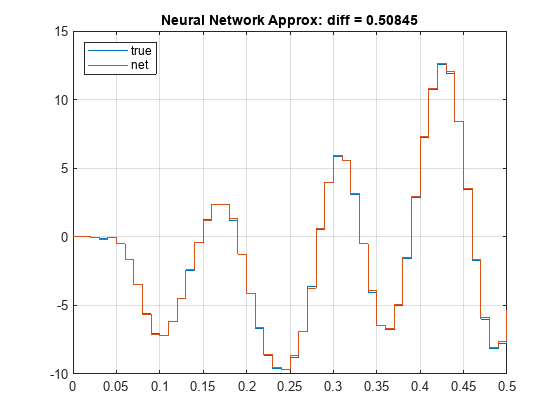

stairs(t',[y' z']);
legend("true","net",Location="northwest");
title(['Neural Network Approx: diff = ' num2str(norm(y-z)) ])
grid

On the validation dataset, the neural network that was trained starting from the calculated weights is able to perform slightly better than the initial (untrained) network that featured the calculated weights, implying that the trading off between the changes in the system matrices to obtain a smaller static gain worked. 

It is however important to emphasize that the initial starting point for the training (the network featuring the weights calculated from the true system matrices) seems to have a very small attractor, so when adding a non-exceedingly small perturbation (this happens when using a non-exceedingly small learning rate) the training algorithm wanders too far and is not able to find a good, or even comparable, solution. This is indeed clearly shown in the following section.

To test the system linearity, evaluate the response of the trained network to the input sequence 3`*u`.

z3 = predict(snet,3*u');

To compare the outputs, plot the linear system response `3*y` and the network response `z3`.

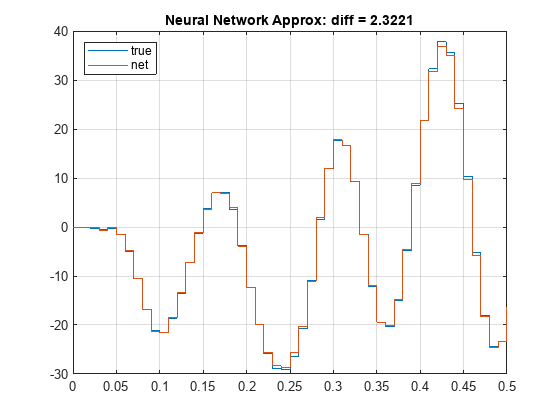

stairs(t',[3*y' z3']);
legend("true","net",Location="northwest");
title(['Neural Network Approx: diff = ' num2str(norm(3*y-z3)) ])
grid

The error increased only slightly more than threefold, confirming that with these weights, when the input is within the range shown in the picture, the network substantially behaves linearly (even though slight deviations from linearity, probably due to the `tansig` functions, seem to appear when the input magnitude is greater than 20). 

## Set the Network Weights Randomly

To see if the training algorithm, when starting from random initial weights, can find a set of weights that yield an acceptable approximation of the true linear system, set the initial matrices randomly.

Set the LSTM weight matrices.

layers(2).InputWeights = rand(4*Nn,Ni);
layers(2).RecurrentWeights = rand(4*Nn,Nn);
layers(2).Bias = rand(4*Nn,1);

Set the LSTM initial states.

layers(2).HiddenState = zeros(Nn,1);
layers(2).CellState = zeros(Nn,1);

Set the weight matrix of the fully connected layer.

layers(3).Weights = rand(No,Nn);
layers(3).Bias = zeros(No,1);

## Define Network Training Options

Since you are starting from random weight, you might want to change some training options such as the learning rate, the number of epochs, and the display frequency. For this example, use an initial learning rate of 0.04, and train the network for 10000 epochs. Display the training progress on the command line once every 500 steps. 

opts = trainingOptions("adam",...
    InitialLearnRate=0.04,...
    LearnRateSchedule="piecewise",...
    LearnRateDropPeriod=100,...
    Plots="none",...
    Verbose=true, ...
    VerboseFrequency=500, ...
    LearnRateDropFactor=0.98,...
    GradientThreshold=1,...
    MaxEpochs=10000);

## Train the Network

To train the network, use `trainNetwork`. Use the same training dataset as before.

snet = trainNetwork(utr',ytr,layers,opts);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |         7.56 |         28.6 |          0.0400 |
|     500 |         500 |       00:00:15 |         2.53 |          3.2 |          0.0369 |
|    1000 |        1000 |       00:00:30 |         1.43 |          1.0 |          0.0333 |
|    1500 |        1500 |       00:00:45 |         1.26 |          0.8 |          0.0301 |
|    2000 |        2000 |       00:01:00 |         1.09 |          0.6 |          0.0272 |
|    2500 |        2500 |       00:01:15 |         0.98 |          0.5 |          0.0246 |
|    3000 |        3000 |       00:01:30 |         0.91 |         

Both the `Mini-batch` `RMSE` and the `Mini-batch` `Loss` are very large at the beginning, but the training algorithm is able so steadily decrease them. After 10000 epochs both measures approach values that are comparable to the ones seen in the previous training run.

It is important to highlight (and easy to verify) that the solution is extremely dependent on both the initial starting point and the various algorithm hyperparameters. For example, changing the third significant digit of the learning rate drop factor can lead to substantially different results.

## Display weights difference

Display the difference between the final weights found by the algorithm and the weights calculated from the true system matrices in the previous section.

(snet.Layers(2).InputWeights-W)'

ans = 1×16 single row vector
    0.0783   -0.1268    0.1176    0.0013    0.0665   -0.0058   -0.1383   -0.0186   -0.1125   -0.0676    0.0907    0.0091   -0.1479    0.2717   -0.5855    0.0836


(snet.Layers(2).RecurrentWeights-R)'

ans = 4×16 single matrix
   -3.5030   -0.8096   -1.1260    1.3146    1.7979   -0.3345   -3.0202    0.7942   -0.4003    1.5625   -0.1774    0.8437    0.6416    0.9981    4.0809   -4.2642
   -1.9408    0.4269   -0.9022    3.4463    0.0184    0.6081   -0.5718   -1.9586   -2.7122   -0.6362   -0.5919   -1.3402    1.7242   -0.3570   -3.1437    0.2207
    0.5047    1.7255    2.9088   -1.4756   -1.2593   -1.4317    0.8854    0.4533    0.9604    0.7241   -0.3445    2.8082    2.2820   -0.0157    2.9580    0.9796
    0.4881   -1.2401    0.1269   -1.2347   -0.4074    0.4053   -1.2871   -1.2080    0.2852   -2.0529   -1.1881   -0.8985   -0.7166    0.2242   -0.1948   -0.5681


(snet.Layers(2).Bias-b)'

ans = 1×16 single row vector
 -100.3160 -100.6701 -100.9082 -101.4210  100.4220  100.7623  101.9829  102.4379   -0.0227    0.0101    0.0026    0.0942  -99.4779  -97.8435  -97.8469  -98.2787


snet.Layers(3).Weights-F

ans = 1×4 single row vector
 -328.4401   99.3505   -7.5004 -188.2302


snet.Layers(3).Bias

ans = single
-1.0190

The solution found by algorithm seems to be quite different from the one found by manually setting the calculated parameters. In particular, it is not clear how linear is the system that is represented by these final weights.

## Compare Outputs

To compare the trained network to the linear system on a different dataset than the training one, evaluate the response of the trained network to the save validation input sequence `u`.

z = predict(snet,u');

To compare the outputs, plot the linear system response `y` and the network response `z`.

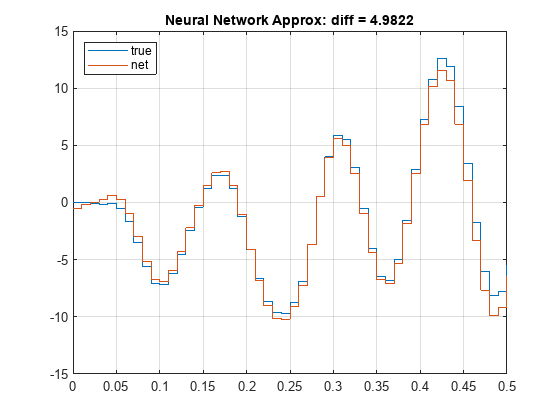

stairs(t',[y' z']);
legend("true","net",Location="northwest");
title(['Neural Network Approx: diff = ' num2str(norm(y-z)) ])
grid

While performance is not as good as in the original network with fixed parameters, it's comparable.

To test the system linearity, evaluate the response of the trained network to the input sequence 3`*u`.

z3 = predict(snet,3*u');

To compare the outputs, plot the linear system response `3*y` and the network response `z3`.

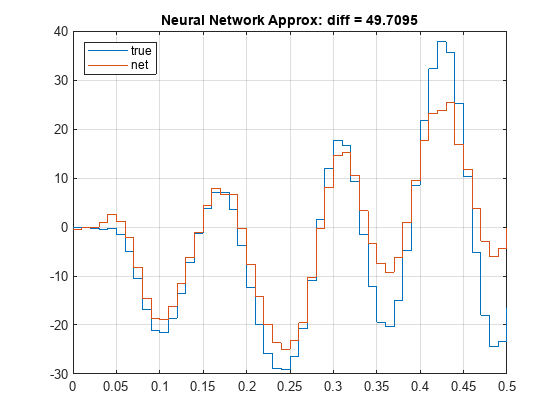

stairs(t',[3*y' z3']);
legend("true","net",Location="northwest");
title(['Neural Network Approx: diff = ' num2str(norm(3*y-z3)) ])
grid

While the response is still acceptable, particularly in the input range from -20 to 20, there is a substantial deviation from linearity for larger inputs. In other words, with these weights, and with inputs magnitude larger 20, the network does not behave as a linear system.

## Conclusions

An LSTM layer is a nonlinear dynamical system in which each unit is associated to two states, the cell state, which feeds back into itself with an "inner" feedback loop, and the "hidden" state which feeds back into itself with an "outer" feedback loop. Two hyperbolic tangent functions in these loops prevent signals from growing indefinitely. The loop signals are also modulated by four "gates". A Simulink representation of the layer was illustrated, and shown to be identical to a network build using layer object from the Deep Learning Toolbox.

A natural question is whether such structure is general enough to approximate any dynamical system, and, if so, whether it can be used for system identification. 

To provide some insight into these questions we have first shown how, given any discrete-time linear dynamical system with matrices $A$, $B$, $C$, and $D=CA^{-1} B$, it is possible to find a set of LSTM weights that approximates it to any degree of accuracy, within a reasonable input range. This was also practically illustrated for a given fourth-order discrete-time linear system.

The next step was to use input and output data collected from the simulation of the same system to train the network, and see if and how well a single LSTM layer could be used to reproduce the system dynamics.

Training the network from the initial set of weights obtained from the $A$, $B$, and $C$ matrices of the true system shows that this solution has a very narrow attractor. Unless a very small learning rate is used, the training algorithm wanders off and is not able to return to the solution, ending up with a set of weights that do not approximate the linear system better than the original set. Conversely, if the learning rate is very small, the training algorithm is able to stay in the proximity of the starting point, and even marginally improve upon its performance (by trading off small changes in the $A$, $B$, and $C$ matrices to obtain a $D\not= CA^{-1} B$ matrix that is closer to the one of the true system).

When starting the training from a random initial point (that is a random set of weights), which is the typical case in system identification (where input and output data is typically all you have), the training algorithm ends up in a local minimum that is quite different from, and does not perform as well as, the solution calculated from the $A$, $B$, and $C$ matrices of the true system.

Furthermore, for the considered one-layer network, the solution is *extremely* dependent on the hyperparameters of the training algorithm. For example, a very minimal change in the learning rate drop factor causes the algorithm to find a different minimum.

It is important to note that networks with more LSTM units and more than one LSTM layer are indeed able to reliably find good approximations of linear systems (including ones in which $D\not= CA^{-1} B$) within a reasonable input range, when starting from random initial weights. 

However, as discussed in an earlier section, such networks pay a price in terms of complexity because the number of parameters of an LSTM scales *quadratically* with the number of units, easily leading to networks having hundreds of thousands of parameters. In turn, this proliferation of parameters leads not only to longer training times, but also to other issues such as the need to properly set all the network internal states. Such issues are very clearly illustrated in the example [Use LSTM Network for Linear System Identification](https://www.mathworks.com/help/ident/ug/use-lstm-for-linear-system-identification.html).

*G. Campa - 31-Jan-2023*